Работа с траекторией:

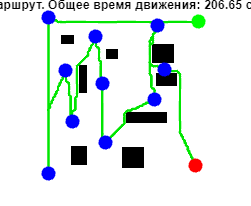

Общее время движения: 206.65 сек


traj = planRoute('img1.png', 5, 2, 2); % получение траектории


x_0 = traj(1, 2)  % Первое значение x

x_0 = 98

y_0 = traj(1, 3)  % Первое значение y

y_0 = 98

theta_0 = traj(1, 4) % Первое значение theta

theta_0 = -1.5708


x_last = traj(end, 2)  % Последнее значение x

x_last = 96

y_last = traj(end, 3)  % Последнее значение y

y_last = 7

theta_last = traj(end, 4) % Последнее значение theta

theta_last = 1.9427

t_end = traj(end, 1);

Задаём параметры модели:

wheel_r = 0.05  % радиус колёс 

wheel_r = 0.0500


wheel_d = 0.02 % ширина колёс

wheel_d = 0.0200


wheel_m = 0.1  % масса колеса

wheel_m = 0.1000


platform_m = 0.5  % масса тележки

platform_m = 0.5000


platform_lx = 0.10  % ширина  тележки

platform_lx = 0.1000


platform_ly = 0.20  % длина тележки

platform_ly = 0.2000


y_i = pi/4  % угол ролика

y_i = 0.7854


n = 4 % количество колёc

n = 4

Расчитываем необходимое для симуляции:

l_w = sqrt(platform_lx^2 + platform_ly^2)   % расстояние от ц.м. колеса до ц.м. платформы

l_w = 0.2236


beta = asin(platform_ly/l_w)  % угол, который понадобится позже в расчётах

beta = 1.1071


I_w = wheel_m*(1/4*wheel_r^2 + 1/12*wheel_d^2 + l_w^2)  % момент инерции колеса относительно ц.м. платформы

I_w = 0.0051


I_p = 1/12 * platform_m * l_w^2  % момент инерции платформы

I_p = 0.0021


I = I_p + n*I_w  % общий момент инерции

I = 0.0223


cos_y_i = cos(y_i) % нужно для симуляции, можно было оставить в симулинке, но так удобнее

cos_y_i = 0.7071


sin_y_i = sin(y_i)

sin_y_i = 0.7071


m = n*wheel_m + platform_m  % общая масса

m = 0.9000


T_0 = [1 0 -platform_ly;     % переход между глобальной системой координат и координатами робота
       0 1  platform_lx;
       0 0  1]          

T_0 =     1.0000         0   -0.2000
         0    1.0000    0.1000
         0         0    1.0000



pinv_T_0 = pinv(T_0)  % переход между координатами робота и глобальной системой координат 

pinv_T_0 =     1.0000    0.0000    0.2000
   -0.0000    1.0000   -0.1000
    0.0000   -0.0000    1.0000



UtoF = [cos_y_i  cos_y_i cos_y_i  cos_y_i;
        -sin_y_i sin_y_i sin_y_i -sin_y_i;
        -l_w     l_w     -l_w     l_w] % переход между u и F колёс 

UtoF =     0.7071    0.7071    0.7071    0.7071
   -0.7071    0.7071    0.7071   -0.7071
   -0.2236    0.2236   -0.2236    0.2236



pinv_UtoF = pinv(UtoF) % переход между F колёс и u

pinv_UtoF =     0.3536   -0.3536   -1.1180
    0.3536    0.3536    1.1180
    0.3536    0.3536   -1.1180
    0.3536   -0.3536    1.1180
